load('area_pre_tutti_et1_p1.mat')
load('area_post_tutti_et1_p1.mat')
load('area_pre_tutti_et1_p2.mat')
load('area_post_tutti_et1_p2.mat')

load('area_pre_tutti_sham_p1.mat')
load('area_post_tutti_sham_p1.mat')
load('area_pre_tutti_sham_p2.mat')
load('area_post_tutti_sham_p2.mat')

p_p1_et1=polyfit(area_pre_tutti_et1_p1,area_post_tutti_et1_p1,1);
fit_area_post_p1_et1=polyval(p_p1_et1,[0; area_pre_tutti_et1_p1]);

p_p2_et1=polyfit(area_pre_tutti_et1_p2,area_post_tutti_et1_p2,1);
fit_area_post_p2_et1=polyval(p_p2_et1,[0;area_pre_tutti_et1_p2]);

p_p1_sham=polyfit(area_pre_tutti_sham_p1,area_post_tutti_sham_p1,1);
fit_area_post_p1_sham=polyval(p_p1_sham,[0;area_pre_tutti_sham_p1]);

p_p2_sham=polyfit(area_pre_tutti_sham_p2,area_post_tutti_sham_p2,1);
fit_area_post_p2_sham=polyval(p_p2_sham,[0;area_pre_tutti_sham_p2]);

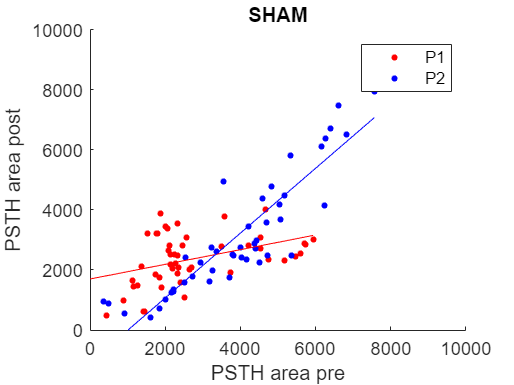

%plot dei due sham
figure
line(area_pre_tutti_sham_p1,area_post_tutti_sham_p1,'color','r','linestyle','none','marker','.','MarkerSize',10)
hold on
line(area_pre_tutti_sham_p2,area_post_tutti_sham_p2,'color','b','linestyle','none','marker','.','MarkerSize',10)
% plot([0 18000],[0 18000],'r')
plot([0;area_pre_tutti_sham_p1],fit_area_post_p1_sham,'r')
plot([0;area_pre_tutti_sham_p2],fit_area_post_p2_sham,'b')
hold off
xlim([0 10000])
ylim([0 10000])
legend('P1','P2')
xlabel('PSTH area pre')
ylabel('PSTH area post')
title(upper('sham'))
box off

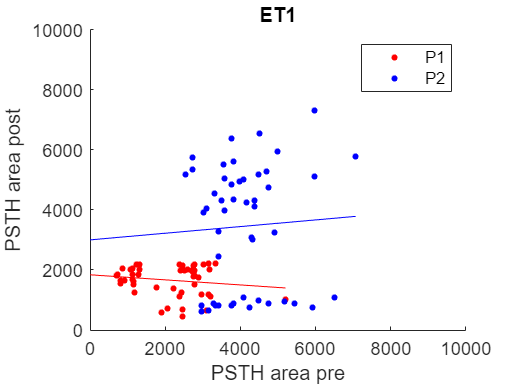

% plot dei due et1
figure
line(area_pre_tutti_et1_p1,area_post_tutti_et1_p1,'color','r','linestyle','none','marker','.','MarkerSize',10)
hold on
line(area_pre_tutti_et1_p2,area_post_tutti_et1_p2,'color','b','linestyle','none','marker','.','MarkerSize',10)
% plot([0 18000],[0 18000],'r')
plot([0; area_pre_tutti_et1_p1],fit_area_post_p1_et1,'r')
plot([0;area_pre_tutti_et1_p2],fit_area_post_p2_et1,'b')
hold off
xlim([0 10000])
ylim([0 10000])
legend('P1','P2')
xlabel('PSTH area pre')
ylabel('PSTH area post')
title(upper('et1'))
box off

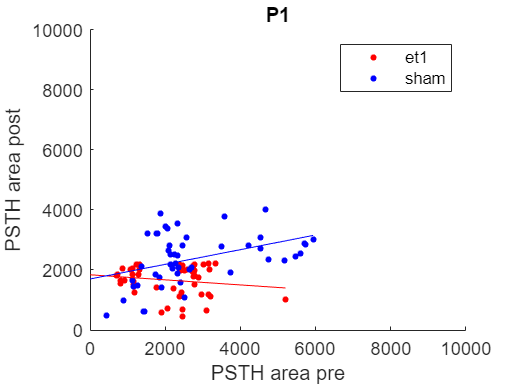

%plot dei due P1
figure
line(area_pre_tutti_et1_p1,area_post_tutti_et1_p1,'color','r','linestyle','none','marker','.','MarkerSize',10)
hold on
line(area_pre_tutti_sham_p1,area_post_tutti_sham_p1,'color','b','linestyle','none','marker','.','MarkerSize',10)
% plot([0 18000],[0 18000],'r')
plot([0; area_pre_tutti_et1_p1],fit_area_post_p1_et1,'r')
plot([0; area_pre_tutti_sham_p1],fit_area_post_p1_sham,'b')
hold off
xlim([0 10000])
ylim([0 10000])
legend('et1','sham')
xlabel('PSTH area pre')
ylabel('PSTH area post')
title(upper('p1'))
box off

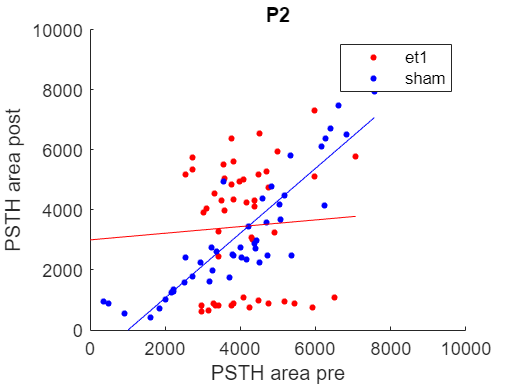

%plot dei due P2
figure
line(area_pre_tutti_et1_p2,area_post_tutti_et1_p2,'color','r','linestyle','none','marker','.','MarkerSize',10)
hold on
line(area_pre_tutti_sham_p2,area_post_tutti_sham_p2,'color','b','linestyle','none','marker','.','MarkerSize',10)
% plot([0 18000],[0 18000],'r')
plot([0; area_pre_tutti_et1_p2],fit_area_post_p2_et1,'r')
plot([0; area_pre_tutti_sham_p2],fit_area_post_p2_sham,'b')
hold off
xlim([0 10000])
ylim([0 10000])
legend('et1','sham')
xlabel('PSTH area pre')
ylabel('PSTH area post')
title(upper('p2'))
box off